x = 0:0.01:2;
y = 0.5 + x + randn(1, length(x));
data = [x', y'];
dist = pdist2(data, data, "euclidean");

[~,pca_score,~,~,pca_explained,~] = pca(data);
[mds_score, mds_eigenvalue] = cmdscale(dist);

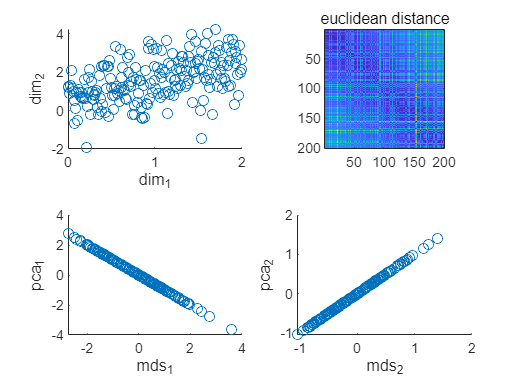

figure();
subplot(2,2,1)
scatter(x,y);
xlabel('dim_1');
ylabel('dim_2');

subplot(2,2,2);
imagesc(dist);
title('euclidean distance')
axis square;

subplot(2,2,3);
scatter(mds_score(:,1), pca_score(:,1));
xlabel('mds_1'); ylabel("pca_1");

subplot(2,2,4);
scatter(mds_score(:,2), pca_score(:,2));
xlabel('mds_2'); ylabel("pca_2");